# Stage 5 - Trend Decomposition

## trend_analysis.mlx

#### Fits a 3-year moving average to one crime category from the South African crime statistics dataset for separation of underlying trend from year-to-year noise by:

- Loading the `sa_crime_clean` CSV from `data/processed/sa_crime_clean.csv,`

- Extracting the `Contact` crime incidents and aggregating it to a national annual series,

- Applying a 3-year centered moving average to smooth year-to-year variation in the `Contact` series, 

- Producing a visualisation displaying the historical series, smoothed moving average, a linear trendline, and COVID-19 anomaly, and

- Exporting and saving the produced visualisation to `matlab/ `for the technical reporting stage in the project pipeline.

## `Data source: `[`Crime Statistics of South Africa (2011-2023)`](https://www.kaggle.com/datasets/harutyunagababyan/crime-stats-of-south-africa-2011-2023)

Starts each script execution on a clean state:

clear all %#ok<CLALL>
clc

Navigates from the live script to the project root, i.e. since the script lives in `matlab/`, goes up one level to reach project root:

active_script = matlab.desktop.editor.getActiveFilename;                    % gets full directory path of live script
script_dir = fileparts(active_script);                                      % gets 'matlab/' directory by filename stripping 
project_root = fileparts(script_dir);                                       % goes up one level to project root
cd(project_root)                                                            % changes path to project root

disp(pwd)

C:\Users\Wits-User\Desktop\PROJECTS\sa-crime-statistics


Loads processed data from file into data table:

import_opts = detectImportOptions('data/processed/sa_crime_clean.csv'); 
import_opts.VariableNamingRule = 'preserve';                                % preserves original column names

sa_crime_tbl = readtable('data/processed/sa_crime_clean.csv', import_opts);  

disp('Crime statistics dataset read into table!')

Crime statistics dataset read into table!


Filters `sa_crime_tbl `to the crime category` Contact` and aggregates incident counts to a national annual series:

contact_idx = strcmp(sa_crime_tbl.crime_category, 'Contact');              % array of indices with row entries being in 'Contact' category
contact_tbl = sa_crime_tbl(contact_idx, :);

crime_years = unique(contact_tbl.financial_year);                          % expected: [2011, 2012, ..., 2021, 2022]

% creates function to aggregate crime counts by year for crime totals:
crime_totals = arrayfun(@(yr) sum(contact_tbl.incident_count(contact_tbl.financial_year == yr)), crime_years);     % passes 'crime_years' as input array

disp([crime_years, crime_totals])

        2011      615935
        2012      608724
        2013      611574
        2014      616973
        2015      623223
        2016      608321
        2017      601366
        2018      617210
        2019      621282
        2020      535217
        2021      607163
        2022      653659



Applies a 3-year centered moving average to `crime_totals` for year-to-year noise smoothing, and fits a linear trend to the smoothed data. The slope of the linear trend provides an indication of the average change in annual `Contact` crime incidents across the 12-year period:

sliding_window = 3;                                                     % moving window length

smoothed_contact = movmean(crime_totals, sliding_window);               % 3-year centered moving average

linear_fit = polyfit(crime_years, crime_totals, 1);                     % fits linear trend
trend_line = polyval(linear_fit, crime_years);                          % evaluates trend yearly

fprintf('Trend slope: %.0f incidents per year.\n', linear_fit(1))        % displays linear trend slope

Trend slope: -479 incidents per year.


Produces the trend decomposition visualisation in the form of a multi-line chart with the following components: the historical `Contact` crime series, the 3-year moving average, and the linear trendline, with the COVID lockdown period specifically annotated:

covid_yr = find(crime_years == 2020);                                   % index for COVID lockdown period
covid_count = crime_totals(covid_yr);                                   % crime total for COVID lockdown period

figure('Units', 'inches', 'Position', [0, 0, 9, 6])   % inches for cleaner look

plot(crime_years, crime_totals,      '-o',  'Color', '#2E7D32', 'LineWidth', 2, 'MarkerFaceColor', '#2E7D32', 'DisplayName', 'Actual')
hold on
plot(crime_years, smoothed_contact,  '-.o', 'Color', '#1565C0', 'LineWidth', 2, 'MarkerFaceColor', '#1565C0', 'DisplayName', '3-year Moving Average')
plot(crime_years, trend_line,        ':',   'Color', '#595959', 'LineWidth', 2, 'DisplayName', 'Linear trend')

% adds COVID annotation:
annotation('textarrow',                         ...
    [0.72, 0.82],                              ...
    [0.30, 0.17],                               ...
    'String',    sprintf('COVID-19\nLockdown'), ...
    'Color',     '#DC143C',                     ...
    'FontSize',   11,                           ...
    'FontAngle', 'italic')

% chart formatting:
xlabel('Year',                              'FontSize', 11)
ylabel('Total Crime Incidents (Thousands)', 'FontSize', 11)
title('Contact Crime - Trend Decomposition (2011-2022)', ...
      'FontSize', 13, 'FontWeight','bold')

xticks(crime_years)

% formats y ticks to thousands annotation:
vals_yticks = get(gca, 'YTick');
yticklabels(arrayfun(@(y_vals) sprintf('%d', round(y_vals/1e3)), vals_yticks, 'UniformOutput', false))    % returns cell array

set(gca, 'LooseInset', get(gca, 'TightInset'))

legend('Location', 'northwest', 'FontSize', 10)
grid on
box  off
hold off                

Exports and saves produced chart to file:

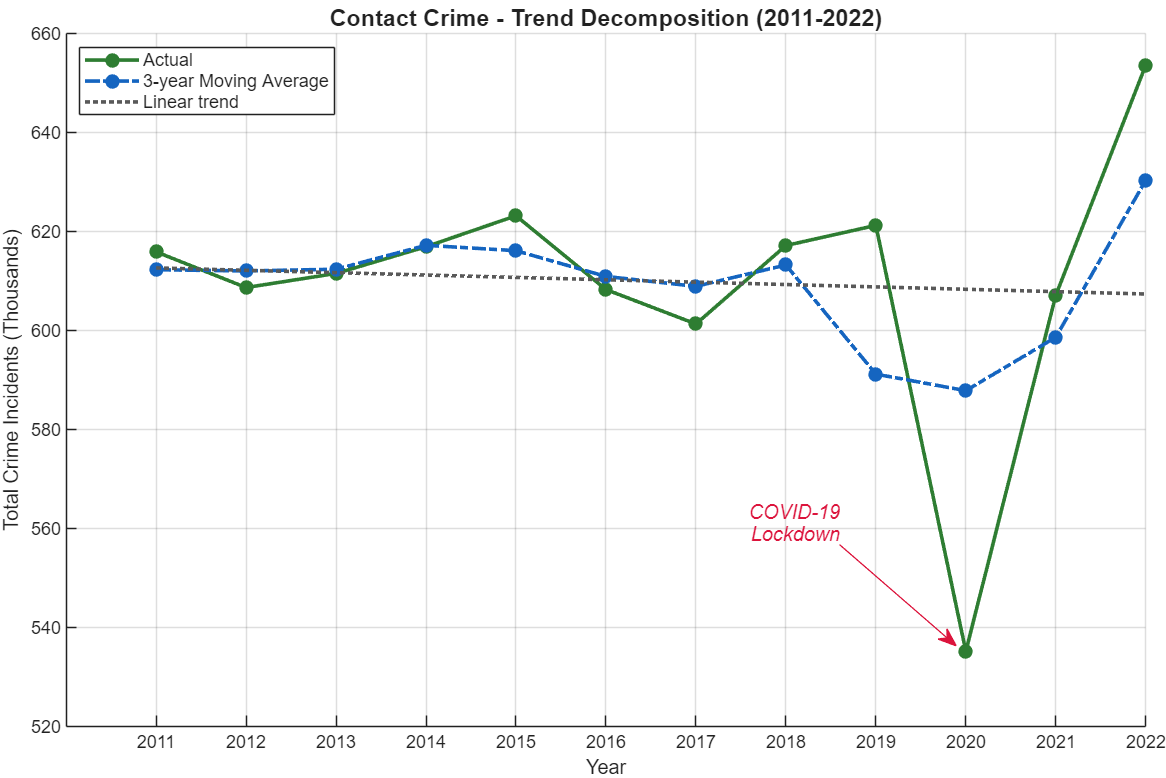

print('-dpng', '-r300', 'matlab/trend_analysis.png')
print('-dpng', '-r300', 'reports/figures/trend_analysis.png')

disp('Export complete: matlab/trend_analysis.png')

Export complete: matlab/trend_analysis.png


The output of this script are as follows: one visualisation `trend_analysis.png` saved to `matlab/`. This singular output is ready for use in the technical reporting stage of the project pipeline. 